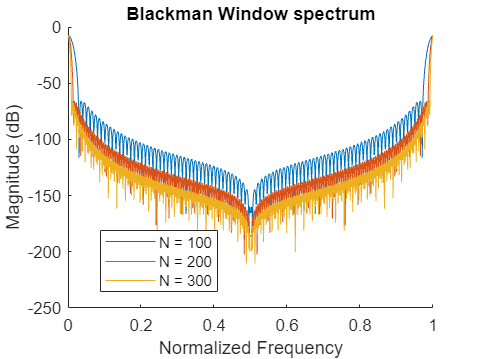

N_values = [100, 200, 300];
Np = 1024;
frequencies = linspace(0, 1, Np);


figure;

hold on;

for i = 1:length(N_values)
    N = N_values(i);
    
    window = blackman(N);   
  
    window_padded = [window; zeros(Np - N, 1)];    
    
    window_spectrum = fft(window_padded);   
    
    window_spectrum_magnitude = abs(window_spectrum) / N;
    
    
    plot(frequencies, 20 * log10(window_spectrum_magnitude), 'DisplayName', ['N = ', num2str(N)]);
end

hold off;

title('Blackman Window spectrum');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
xlim([0, 1]);
legend('Location','best');

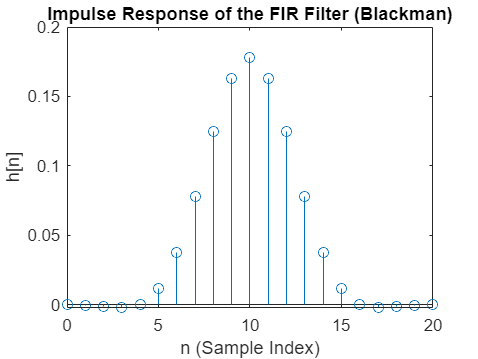


%alpha = 2; 
N = 21;
wc = pi/3; 
window_b=blackman(N);
window_r=rectwin(N);

h_b = fir1(N - 1, wc / (2 * pi), 'low', window_b);
figure;
stem(0:N-1, h_b);
title('Impulse Response of the FIR Filter (Blackman)');
xlabel('n (Sample Index)');
ylabel('h[n]');

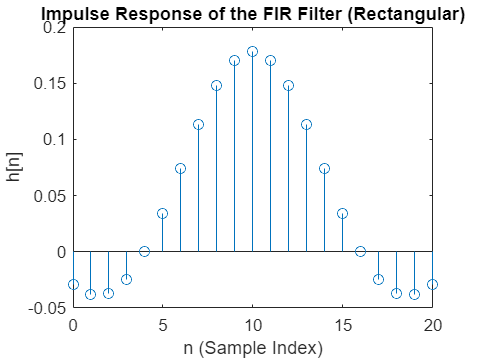


figure;
h_r = fir1(N - 1, wc / (2 * pi), 'low', window_r);
figure;
stem(0:N-1, h_r);
title('Impulse Response of the FIR Filter (Rectangular)');
xlabel('n (Sample Index)');
ylabel('h[n]');

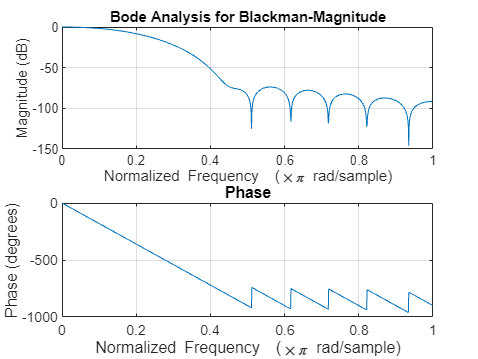


figure;
freqz(h_b,1,1024)
title('Bode Analysis for Blackman-Magnitude')

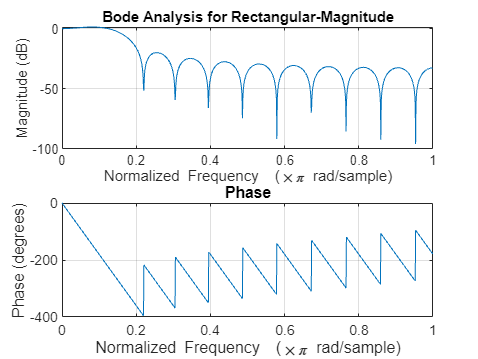

figure;
freqz(h_r,1,1024)
title('Bode Analysis for Rectangular-Magnitude')

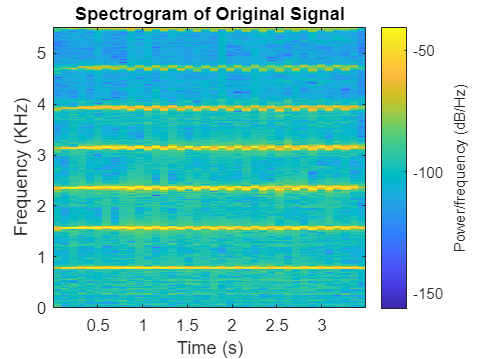



audioFileName = 'instru2.wav';
[y, Fs] = audioread(audioFileName);

windowSize = 1024;  
overlap = 10;    
spectrogram(y, windowSize, overlap, [], Fs, 'yaxis');
title('Spectrogram of Original Signal');
xlabel('Time (s)');
ylabel('Frequency (KHz)');


N=length(y);
Y=fft(y);
freq_axis=Fs*((0:N-1)/N);
mag=abs(Y);
[~, idx] = max(mag(2:end));
fundamental_freq= freq_axis(idx)

fundamental_freq = 2.3688e+03

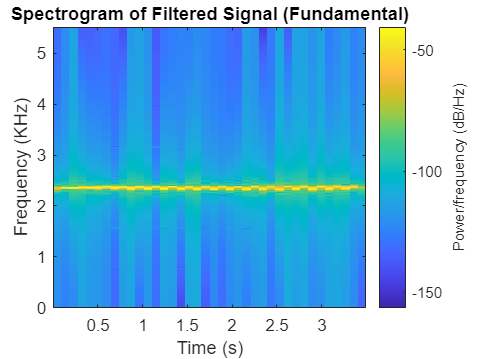



cutoffFrequency = fundamental_freq;  
N = 101;  
window_b=blackman(N);
h = fir1(N-1, [fundamental_freq- 10, fundamental_freq + 10] / (Fs / 2),'bandpass',window_b);

filteredSignal = filter(h, 1, y);

filteredFileName = 'filtered_instru.wav';
audiowrite(filteredFileName, filteredSignal, Fs);


sound(filteredSignal, Fs);


spectrogram(filteredSignal, windowSize, overlap, [], Fs, 'yaxis');
title('Spectrogram of Filtered Signal (Fundamental)');
xlabel('Time (s)');
ylabel('Frequency (KHz)');